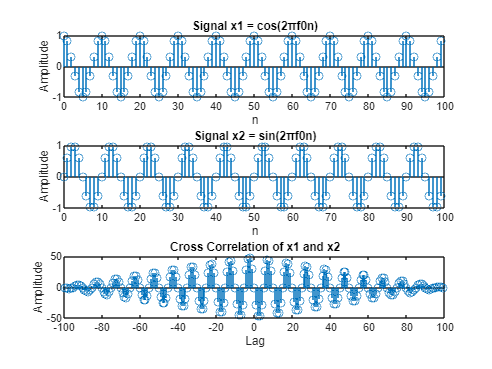

% Define the time axis
n = 0:99; % 100 samples for 10 time periods

% Generate the first discrete time sinusoidal signal
f0 = 0.1; % Choose a frequency
x1 = cos(2 * pi * f0 * n);

% Generate the second discrete time sinusoidal signal
x2 = sin(2 * pi * f0 * n);

% Find the cross correlation of the two signals
cross_corr = xcorr(x1, x2);

% Plot the signals and the cross correlation
subplot(3,1,1);
stem(n, x1);
xlabel('n');
ylabel('Amplitude');
title('Signal x1 = cos(2πf0n)');

subplot(3,1,2);
stem(n, x2);
xlabel('n');
ylabel('Amplitude');
title('Signal x2 = sin(2πf0n)');

subplot(3,1,3);
stem(-99:99, cross_corr);
xlabel('Lag');
ylabel('Amplitude');
title('Cross Correlation of x1 and x2');